# MAE 240 Final Project Master Live Script

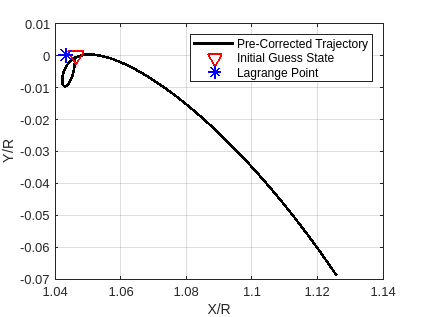

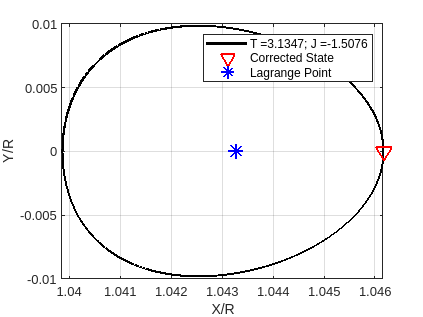

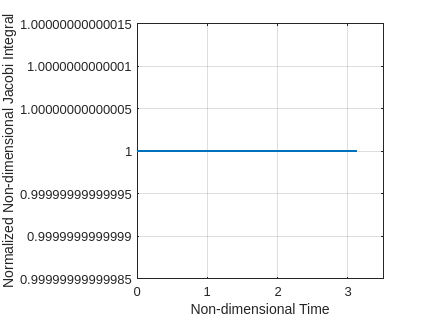

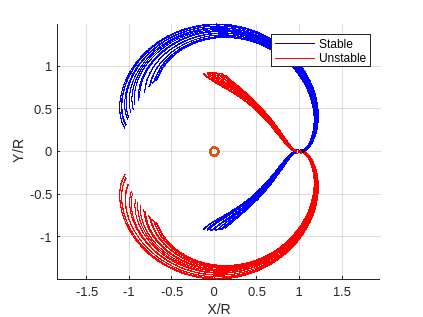

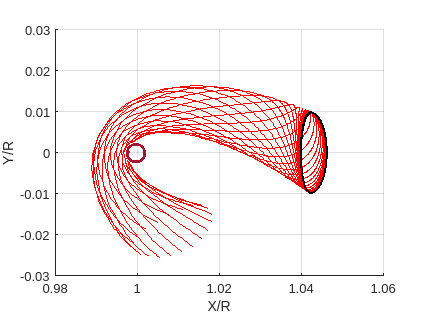

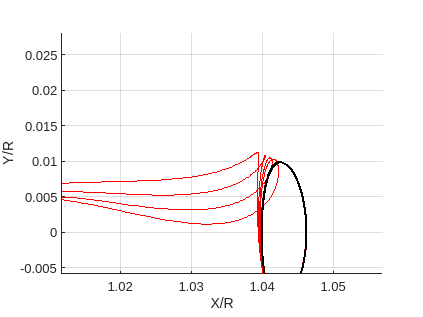

clear
clc
close all
format long
%-------------------------------------------------------------------------%
%                              Inputs Guide                               %
%-------------------------------------------------------------------------%

% L    :   a string containing the colinear Lagrange point to be used in
%          Lyapunov orbit determination; has the form 'L1', 'L2', or 'L3'.

% const:   a structure array containing the following values
%
% --> mu: the mass ratio of the system, this will be automatically
% calculated using the supplied primary masses.
%
% --> Rprimary: radius of the primary in kg
%
% --> Rsecondary: radius of the secondary in kg
%
% --> R: the distance between the primaries in km
%
% --> eps: the desired precision for the differential correction algorithm
%
% --> disp: the nondimension displacement from the desired Lagrange point
% to be used as the initial condition
%
% --> LOperiod: nondimensional guess for the period of the Lyaponov orbit
% (usually a Lyapunov orbit has a period half that of the primaries i.e.
% T_LO = pi)
%
% --> nm: number of stable manifold trajectories desired
%
% --> manprop: number of periods (of the primaries) to propagate the
% manifold trajectories backward
%
% --> I: max number of iterations for differential correction method



%-------------------------------------------------------------------------%
%                          Configuartion Values                           %
%-------------------------------------------------------------------------%

% Recommended Config Values
%
%  L1  :    disp < 5.5e-3   for   LOperiod = pi
%
%  L2  :    disp < 3.1e-3   for   LOperiod = pi
%
%  L3  :    disp < 1.1e-1   for   LOperiod = 1.2*pi


% Define the Lagrange point of interest and Lyapunov orbit characteristics
L = 'L2';
const.disp = 2.9e-3;
const.LOperiod = 1*pi;

% Define the specific parameters of the primaries of interest
m_primary = 5.683e26; % [kg]
m_secondary = 1.3452e23; % [kg]
const.Rprimary = 58232; % [km]
const.Rsecondary = 2574.7; % [km]
const.R = 1.2e6; % [km]

const.mu = m_secondary/(m_primary + m_secondary);


% Define the configuration values for the differential correction and
% manifold propagation methods
const.eps = 1e-10;
const.I = 10;
const.manprop = 4;
const.nm = 20;



%-------------------------------------------------------------------------%
%                           Main Function Call                            %
%-------------------------------------------------------------------------%

[X, Phi, X_LP, J] = LyapunovOrbit(L, const);